Dynamics of the entropy in measurement only model (factorized ensemble):

clear
close all
rng default

L = 25; 
r = 3;
RealizationsNumber = 200; % experiments number
SimulationMaxTime2 = L*L; % simulation steps
TimeSequence = 1:L:SimulationMaxTime2;

h_mat = zeros(numel(TimeSequence), L, RealizationsNumber);
I3_mat = zeros(numel(TimeSequence),RealizationsNumber);

% define the parameters of the measurement ensemble:
ensemble.L = L; % total qubits number, minus the reference qubit
ensemble.r = r; % pauli string length
ensemble.qx = 0.15;
ensemble.qy = 0.85;
ensemble.qz = 1 - ensemble.qx - ensemble.qy;
ensemble.bc = 'open';

%Suppose the initial state is stabilized by {Z_i}:
Tableau0 = [zeros(L), eye(L)];

tic;
parfor i_r = 1:RealizationsNumber % replaced by 'for' if not using parallel
    I3_mat_i_r = zeros(numel(TimeSequence),1);
    h_mat_i_r = zeros(numel(TimeSequence),L);
    % sampling a list of generators from the ensemble:
    [newrow_list] = tableau_newrow_FactEns(ensemble,SimulationMaxTime2);
    Tableau = Tableau0;
    % start running
    for i_t = 1:SimulationMaxTime2
        newrow = newrow_list(i_t,:);
        Tableau = UpdateTableau(Tableau, newrow);
        if ismember(i_t,TimeSequence) == 1
            seq_ind = find(TimeSequence == i_t);
            h_mat_i_r( seq_ind ,:) = heightfunc(Tableau, 'pure');
            
            RegionA_index = round(L/8):round(L/8+L/4);
            RegionB_index = round(L/8+L/4+1):round(L/8+L/2);
            RegionC_index = round(L/8+L/2+1):round(L/8+3*L/4);
            I3_mat_i_r(seq_ind,1) = tripartiteMI(Tableau, RegionA_index, RegionB_index, RegionC_index);
        end
    end
    I3_mat(:,i_r) = I3_mat_i_r;
    h_mat(:,:,i_r) = h_mat_i_r;
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


t_spreading = toc;
fprintf(1,'The simulation is done, elapsed time: %4.2f seconds. \n', t_spreading);

The simulation is done, elapsed time: 72.83 seconds. 



h_mat_avg = mean(h_mat,3);
I3_avg = mean(I3_mat,2);


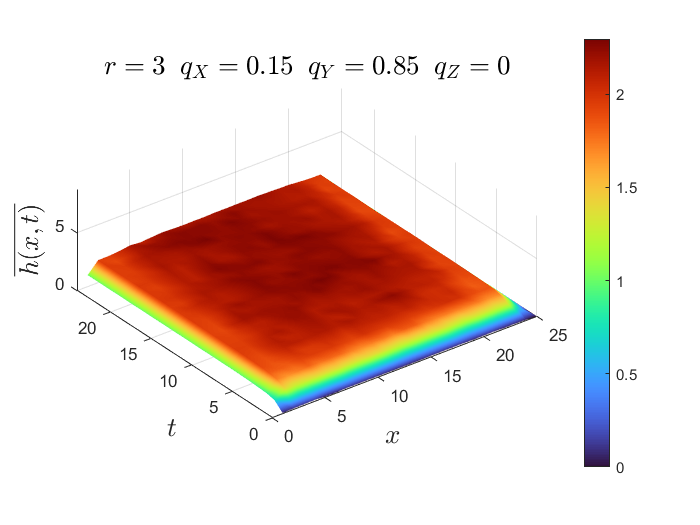


figure;
fsz= 16;

surf((1:L),TimeSequence/L,h_mat_avg);
shading interp
xlabel('$x$','interpreter','latex','FontSize',fsz);
ylabel('$t$','interpreter','latex','FontSize',fsz);
zlabel('$\overline{h(x,t)}$','interpreter','latex','FontSize',fsz)

title(['$r = ',num2str(r),'\;\;q_X = ',num2str(ensemble.qx),'\;\; q_Y = ',num2str(ensemble.qy), ...
    '\;\;q_Z = ',num2str(ensemble.qz),'$'], 'Interpreter','latex','FontSize',fsz)
xlim([0,L]);
ylim([0,max(TimeSequence/L)]);    
zlim([0,0.7*L/2]);
colorbar;
colormap(turbo)
caxis([0,max(max(h_mat_avg))]);
daspect([1,1,1])

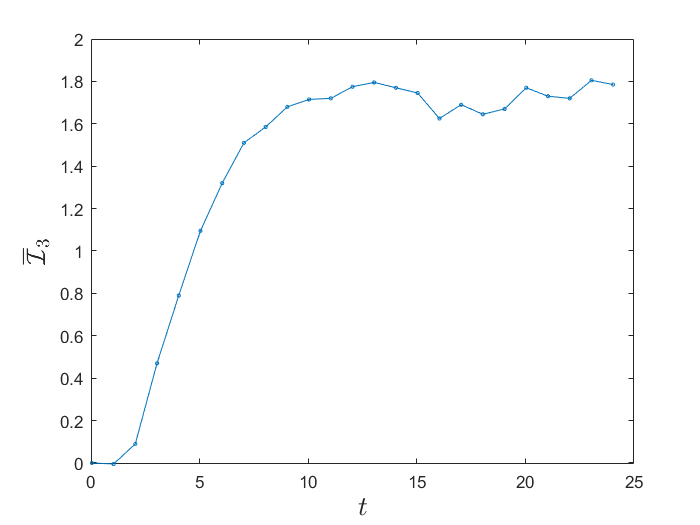

set(gcf,'color','w');

figure;
plot(TimeSequence/L,I3_avg,'-o','MarkerSize',2);
xlabel('$t$','interpreter','latex','FontSize',fsz);
ylabel('$\overline{\mathcal{I}}_3$','interpreter','latex','FontSize',fsz);

Information spreading

clear
close all
rng default

L = 47+1; % be an even number for convenience
r = 3;
RealizationsNumber = 20; % 
SimulationMaxTime2 = L*L/2; % simulation time steps
TimeSequence = 1:L:SimulationMaxTime2;

f_mat = zeros(numel(TimeSequence), L - 1,RealizationsNumber);


% define the parameters of the measurement ensemble:
ensemble.L = L - 1; % total qubits number, minus the reference qubit
ensemble.r = r; % pauli string length
ensemble.qx = 1/3;
ensemble.qy = 1/3;
ensemble.qz = 1 - ensemble.qx - ensemble.qy;
ensemble.bc = 'open'; % boundary condition MUST be open, in this case

%Suppose the initial state is stabilized by {Z_i}:
Tableau0 = [zeros(L), eye(L)];
% Tableau0(:,[L,2*L]) = zeros(L,2);
Generators0.Tableau = Tableau0;
Generators0.SignVector = zeros(L,1);
% Code in Bell pairs, with reference qubit R
% Here qubit R is the last site (x = L), which is the control qubit
% the target qubit is the middle site of the chain: x = L/2
Generators0 = CliffordOperation(Generators0,'H',L);
Generators0 = CliffordOperation(Generators0,'CNOT',[L,L/2]);
Tableau0 = Generators0.Tableau;


tic;
parfor i_r = 1:RealizationsNumber % replaced by 'for' if not using parallel
    f_mat_i_r = zeros(numel(TimeSequence),L - 1);
    % sampling a list of generators from the ensemble:
    [newrow_list] = tableau_newrow_FactEns(ensemble,SimulationMaxTime2);
    Tableau = Tableau0;
    % start running
    for i_t = 1:SimulationMaxTime2
        newrow0 = newrow_list(i_t,:); 
        newrow = [newrow0(1:L-1),0, newrow0((1:L-1)+(L-1)),0]; % complement the reference qubit
        Tableau = UpdateTableau(Tableau, newrow); %perform measurement
        if ismember(i_t,TimeSequence) == 1
            seq_ind = find(TimeSequence == i_t);
            for i_x = 0:(L/2 - 1)
                if i_x == 0
                    f_mat_i_r( seq_ind , L/2) = bipartiteMI(Tableau, L/2, L);
                else
                    f_mat_i_r( seq_ind , L/2 + i_x) = bipartiteMI(Tableau, ((L/2 - i_x): (L/2 + i_x)), L);
                    f_mat_i_r( seq_ind , L/2 - i_x) = f_mat_i_r( seq_ind , L/2 + i_x);
                end
            end
        end
    end
    f_mat(:,:,i_r) = f_mat_i_r;
end
t_spreading = toc;
fprintf(1,'The information spreading simulation is done, elapsed time: %4.2f seconds. \n', t_spreading);

The information spreading simulation is done, elapsed time: 38.23 seconds. 


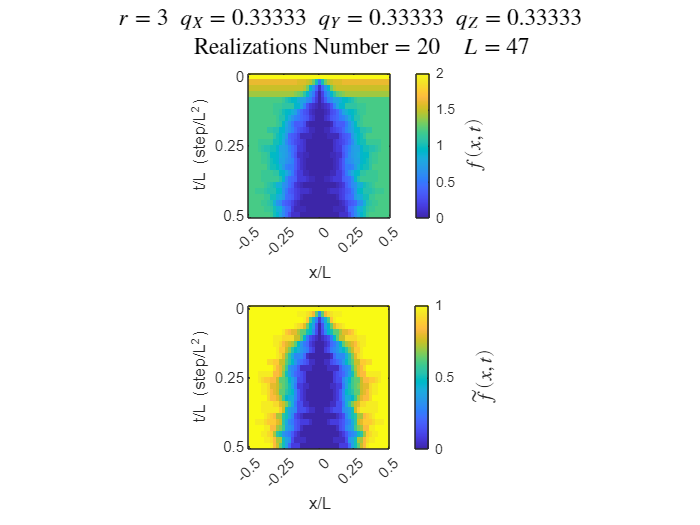


f_mat_avg = mean(f_mat,3);
tilde_f_mat_avg = f_mat_avg./(f_mat_avg(:,1).*ones(1,L-1));


figure;

subplot(2,1,1)
ymax = SimulationMaxTime2/(L^2);
imagesc([-0.5,0.5],[0,ymax],f_mat_avg);
daspect([2,1,1]);
xlabel('x/L');
ylabel('t/L (step/L^2)');
set(gca,'XTick',[-0.5,-0.25,0,0.25,0.5],'XTickLabel',{'-0.5','-0.25','0','0.25','0.5'});
set(gca,'YTick',[0,1/4,1/2,3/4,1],'YTickLabel',{'0','0.25','0.5','0.75','1'});
h = colorbar;
ylabel(h, '$f(x,t)$','Interpreter','latex','FontSize',12)
caxis([0,2]);
daspect([2,1,1]);

subplot(2,1,2)
imagesc([-0.5,0.5],[0,ymax],tilde_f_mat_avg);
daspect([2,1,1]);
xlabel('x/L');
ylabel('t/L (step/L^2)');
set(gca,'XTick',[-0.5,-0.25,0,0.25,0.5],'XTickLabel',{'-0.5','-0.25','0','0.25','0.5'});
set(gca,'YTick',[0,1/4,1/2,3/4,1],'YTickLabel',{'0','0.25','0.5','0.75','1'});
h = colorbar;
ylabel(h, '$\tilde{f}(x,t)$','Interpreter','latex','FontSize',12)
caxis([0,1]);
daspect([2,1,1]);

sgtt = sgtitle({['$r = ',num2str(r),'\;\;q_X = ',num2str(ensemble.qx),'\;\; q_Y = ',num2str(ensemble.qy), ...
    '\;\;q_Z = ',num2str(ensemble.qz),'$']; ...
    ['$\quad\mathrm{Realizations\;Number} = ',num2str(RealizationsNumber),'\quad L =',num2str(L-1),'$']});
set(sgtt,'interpreter','latex');

set(gcf,'color','w');




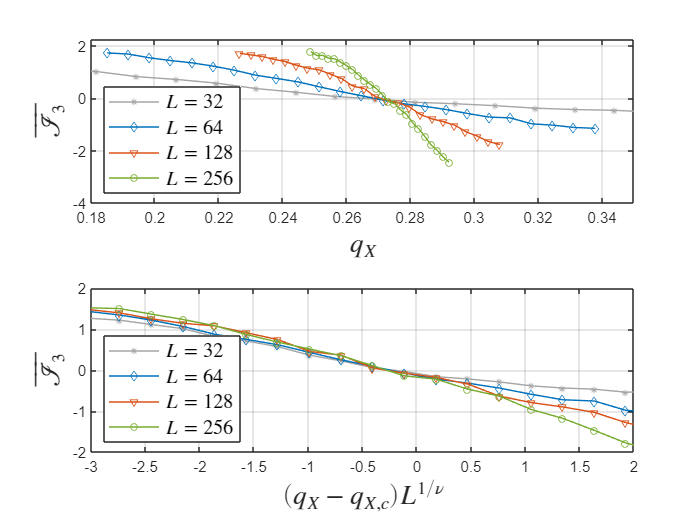

addpath('I_3_stat');
combine_and_plot_I3_data

function [I2] = bipartiteMI(Tableau, RegionA_index, RegionB_index)
% compute the bipartite mutual information, between Region A & B.
S_A = TableauSubRegion2Entropy(Tableau, RegionA_index);
S_B = TableauSubRegion2Entropy(Tableau, RegionB_index);
S_AB = TableauSubRegion2Entropy(Tableau, [RegionA_index,RegionB_index]);

I2 = S_A + S_B  - S_AB;

end

function [I3] = tripartiteMI(Tableau, RegionA_index, RegionB_index, RegionC_index)

S_A = TableauSubRegion2Entropy(Tableau, RegionA_index);
S_B = TableauSubRegion2Entropy(Tableau, RegionB_index);
S_C = TableauSubRegion2Entropy(Tableau, RegionC_index);
S_AB = TableauSubRegion2Entropy(Tableau, [RegionA_index,RegionB_index]);
S_BC = TableauSubRegion2Entropy(Tableau, [RegionB_index,RegionC_index]);
S_CA = TableauSubRegion2Entropy(Tableau, [RegionA_index,RegionC_index]);
S_ABC = TableauSubRegion2Entropy(Tableau, [RegionA_index,RegionB_index,RegionC_index]);

I3 = S_A + S_B + S_C + S_ABC - S_AB - S_BC - S_CA;
end